Label = readtable('MyData.xlsx', 'Range','A1:A16');
Label = Label{:,:};
MyData = readtable('MyData.xlsx', 'Range','B1:P16');

MyData = NormMatrix(MyData{:,:});
MyData1 = MyData;
MyData = MyData.*MyData;
n = 15;

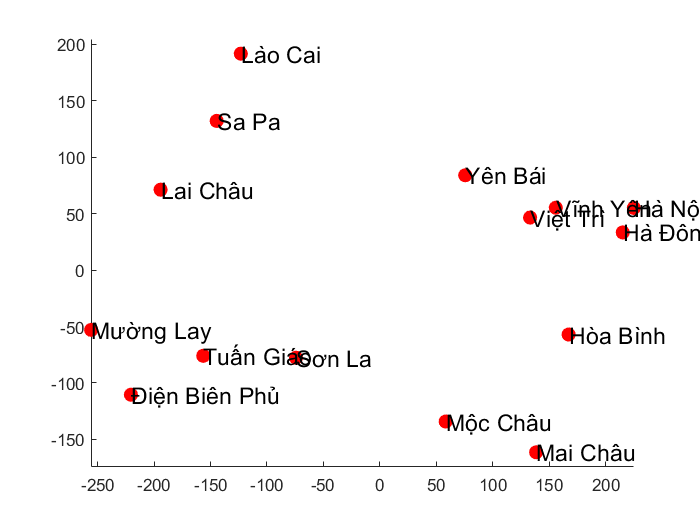

H = eye(n) - 1/n*ones;
B = -1/2*H*MyData*H;
[w,v] = eig(B);
C1 = [w(:, 1:2)] * [sqrt(v(1,1)) 0; 0 sqrt(v(2,2))];
figure;
scatter(C1(:,1), C1(:,2), 72, "red", 'filled');
text(C1(:,1), C1(:,2), Label, 'FontSize', 14);
axis equal;

Good(C1, MyData1)

ans = 0.1159

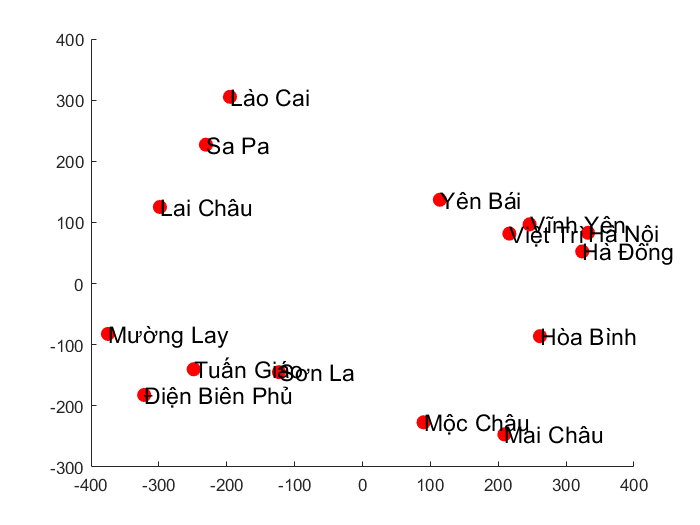

Const = AddCons(MyData1);
[C2, k ] = Coor(NewDis(MyData1, Const));
figure;
axis equal;
scatter(C2(:,1), C2(:,2), 72, "red", 'filled');
text(C2(:,1), C2(:,2), Label, 'FontSize', 14);

Good(C2, NewDis(MyData1, Const))

ans = 0.3431